filelist = [ "data_21-Mar-2025_09-26-10.mat" ,
"data_21-Mar-2025_09-28-59.mat" ,
"data_21-Mar-2025_09-32-07.mat" ,
"data_21-Mar-2025_09-34-30.mat" ,
"data_21-Mar-2025_09-37-20.mat" ,
"data_21-Mar-2025_09-42-10.mat" ,
"data_21-Mar-2025_09-43-30.mat" ,
"data_21-Mar-2025_09-51-00.mat" ,
"data_21-Mar-2025_09-52-42.mat" ,
"data_21-Mar-2025_09-55-40.mat" ,
"data_21-Mar-2025_10-02-58.mat" ,
"data_21-Mar-2025_10-09-11.mat" ,
"data_21-Mar-2025_10-10-37.mat" ,
"data_21-Mar-2025_10-12-01.mat" ,
"data_21-Mar-2025_10-17-54.mat" ,
"data_21-Mar-2025_10-21-14.mat" ,
"data_21-Mar-2025_10-24-43.mat" ,
"data_21-Mar-2025_10-29-46.mat" ,
"data_21-Mar-2025_10-36-06.mat" ];

exp_id = 18

exp_id = 18

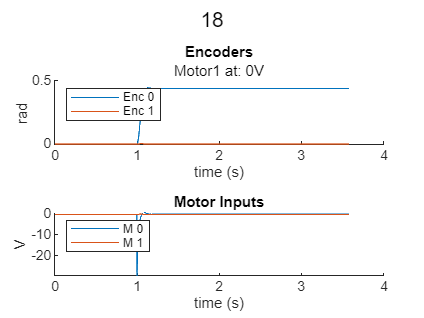

filename = "lab3/data/pid/" + filelist(exp_id);
load(filename,"data")

smartPlotEncVoltage(data,exp_id,false);

norm = 1;
angle_ref = 25;


t = data(1,:)-1;
y = rad2deg(data(2,:))/norm;
y_ref = angle_ref*(0.5 + 0.5*sign(t));

figure
plot(t,y_ref,":")
hold on
plot(t,y,"b")

xlim([0 0.3])
title("Step Response M0 (PD)")
ylabel("position (deg)")
xlabel("time (s)")

% PID0
Kp = -21.6;
Kd = -0.423;

C0 = pid(Kp,0,Kd);

dc_gain0 = -1.4479 ; % v/(rad/s)
tau0 = 1/24.9218;   % 1/s

G0 = tf([dc_gain0],[tau0 1 0]);

L0 = C0*G0;
L0d = c2d(L0,1/500);

T_pd = feedback(L0d,1);

[y_sim,tOut] = step(T_pd);
stepinfo(T_pd)

ans = struct with fields:
         RiseTime: 0.0640
    TransientTime: 0.1940
     SettlingTime: 0.1940
      SettlingMin: 0.9120
      SettlingMax: 1.0534
        Overshoot: 5.3374
       Undershoot: 0
             Peak: 1.0534
         PeakTime: 0.1300


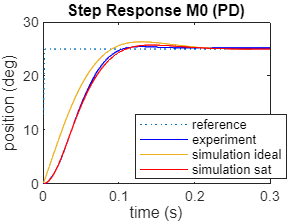

plot(tOut,angle_ref*y_sim)


% PID0 + sat
pidq = "lab3/pidq";
h = load_system(pidq);
simIn = Simulink.SimulationInput(pidq);
simIn= setVariable(simIn,"setP",deg2rad(25));
simIn= setVariable(simIn,"Kp",Kp);
simIn= setVariable(simIn,"Kd",Kd);
simIn= setVariable(simIn,"dcg",dc_gain0);
simIn= setVariable(simIn,"tau",tau0);
out = sim(simIn,"UseFastRestart","on");

% out = sim("lab3/pidq");

t_sim_sat = out.yout{1}.Values.Time;
y_sim_sat = out.yout{1}.Values.Data/norm;
plot(t_sim_sat,y_sim_sat,"r")

save("lab3/out/m0_PD_25deg.mat","t_sim_sat","y_sim_sat")

hold off

legend(["reference","experiment",  "simulation ideal","simulation sat"], "Position", [0.5565 0.2654 0.3041, 0.1544])